D = csvread("4_22_8489.csv")

D = 1.0e+05 *

    0.0985   -0.0000   -0.0000    0.0000   -0.0001    0.0001    0.0000    0.0002    0.0001   -0.0000    0.0008   -0.0002    0.0000    0.0000    0.0000    0.0000    0.0100    0.0000         0         0         0         0         0         0         0         0         0         0         0
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0990   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0002    0.0001   -0.0000    0.0008   -0.0002    0.0000    0.0000    0.0000    0.0000    0.0100    0.0000         0         0         0         0         0         0         0         0         0         0         0
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0008         0  

D_fixed = zeros(floor(length(D(:,1))), 28);

for i = 1:2:length(D(:,1))-1
    D_fixed(end+1,:) = [D(i,1:18) D(i+1,1:10)];
end

D = D_fixed;

D = array2table(D, 'VariableNames',{'curtime','accelx','accely','accelz','gyrox','gyroy','gyroz',...
    'temp', 'eulerx', 'eulery', 'eulerz', 'baralt',  'lng', 'lat', 'gpsalt', 'phs',  'cont', 'volt'...
    'link', 'kfx', 'kfy','kfz',  'kfvx', 'kfvy', 'kfvz', 'kfdrag','d', 'rssi'})

D = 36088×28 table
    curtime    accelx    accely    accelz    gyrox    gyroy    gyroz    temp    eulerx    eulery    eulerz    baralt    lng    lat    gpsalt    phs    cont    volt    link    kfx    kfy    kfz    kfvx    kfvy    kfvz    kfdrag    d    rssi
    _______    ______    ______    ______    _____    _____    _____    ____    ______    ______

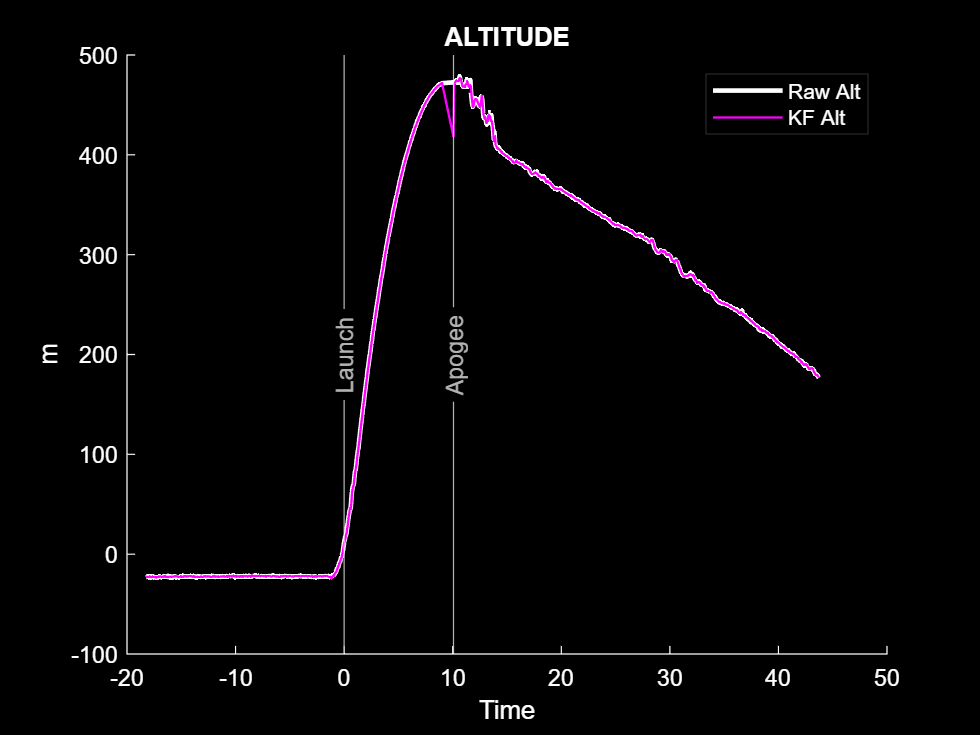

start_idx = 34400;
end_idx = 35459;



phase_events = find(ischange(D.phs));
    

    



figure(1)
clf


set(gca,'Color', [0 0 0])
    set(gca,'XColor',[1 1 1])
    set(gca,'YColor',[1 1 1])
        set(gcf,'Color','k')

    set(gcf, 'InvertHardcopy', 'off');

hold on

plot((D.curtime(start_idx:end_idx) - D.curtime(phase_events(3)))/1000, D.baralt(start_idx:end_idx)', "linewidth", 2, "color", [1 1 1])
plot((D.curtime(start_idx:end_idx) - D.curtime(phase_events(3)))/1000, D.kfz(start_idx:end_idx)', "linewidth", 1, "color", spring(1))
xline((D.curtime(phase_events(3))- D.curtime(phase_events(3)))/1000, "LineWidth", 0.5, "color", [1 1 1], "Label", 'Launch', "LabelHorizontalAlignment","center", "LabelVerticalAlignment","middle")
xline((D.curtime(phase_events(4))- D.curtime(phase_events(3)))/1000, "LineWidth", 0.5, "color", [1 1 1], "Label", 'Apogee', "LabelHorizontalAlignment","center", "LabelVerticalAlignment","middle", "DisplayName", "")




l = legend("Raw Alt", "KF Alt", "", "");
l.TextColor = [1 1 1];
ylabel("m")
xlabel("Time")
title("ALTITUDE", "Color", [1 1 1])
print(gcf,'ALT.png','-dpng','-r600')

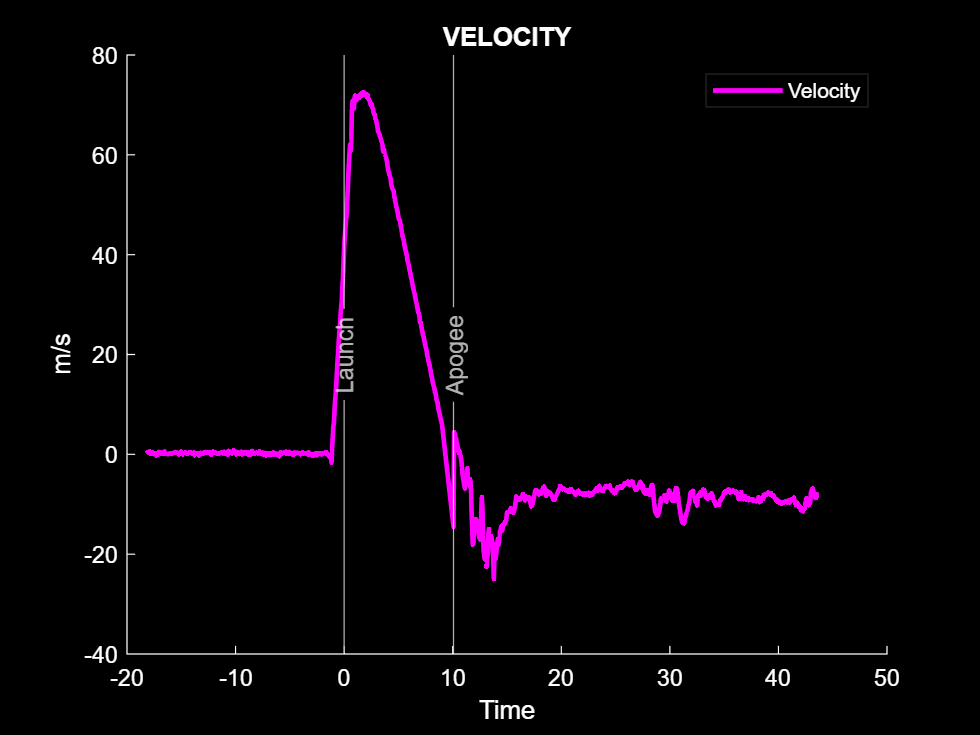


figure(2)
clf


set(gca,'Color', [0 0 0])
    set(gca,'XColor',[1 1 1])
    set(gca,'YColor',[1 1 1])
        set(gcf,'Color','k')

    set(gcf, 'InvertHardcopy', 'off');

hold on

plot((D.curtime(start_idx:end_idx) - D.curtime(phase_events(3)))/1000, D.kfvz(start_idx:end_idx)', "linewidth", 2, "color", spring(1))
xline((D.curtime(phase_events(3))- D.curtime(phase_events(3)))/1000, "LineWidth", 0.5, "color", [1 1 1], "Label", 'Launch', "LabelHorizontalAlignment","center", "LabelVerticalAlignment","middle")
xline((D.curtime(phase_events(4))- D.curtime(phase_events(3)))/1000, "LineWidth", 0.5, "color", [1 1 1], "Label", 'Apogee', "LabelHorizontalAlignment","center", "LabelVerticalAlignment","middle", "DisplayName", "")




l = legend("Velocity", "", "");
l.TextColor = [1 1 1];
ylabel("m/s")
xlabel("Time")
title("VELOCITY", "Color", [1 1 1])
print(gcf,'VEL.png','-dpng','-r600')